# PROYECTO 1 - SHAZAM

# Lab Procedure - Part 1:

`This week you will build the complete training system for Shazam, which extracts the fingerprints from all MP3 files in a designated folder and creates a database. You can use any MP3 files you want.`

`The main steps of this procedure are the following:`

- `Read in the song using mp3read.`

- `Average the two channels, subtract the mean, and downsample.`

- `Compute the spectrogram of the song using spectrogram.`

- `Find the local peaks of the spectrogram by using circshift in a loop.`

- `Threshold the result of step 5 to end up with a specified rate of peaks retained per second of sound.`

- `Find pairs of proximal peaks and add load them into a hash table.`

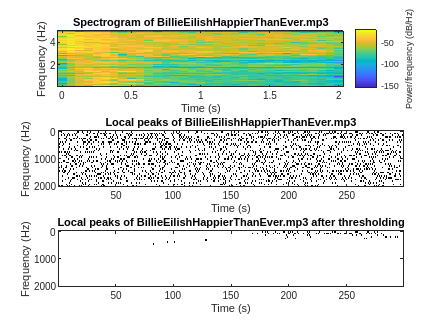

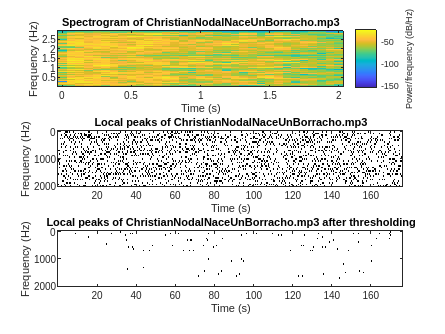

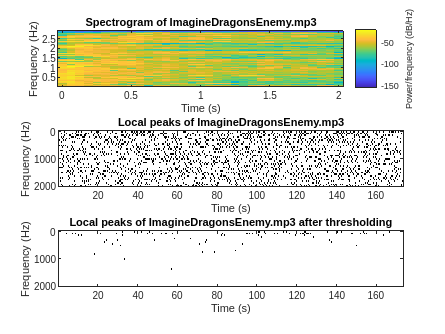

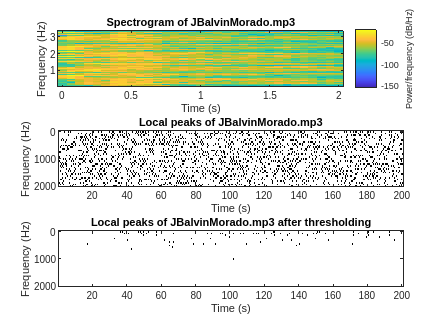

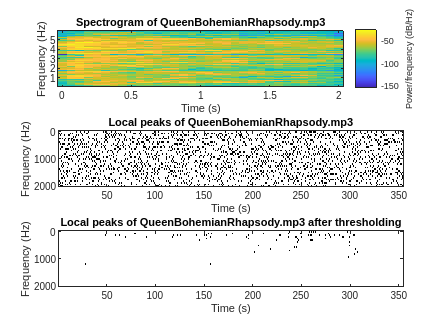

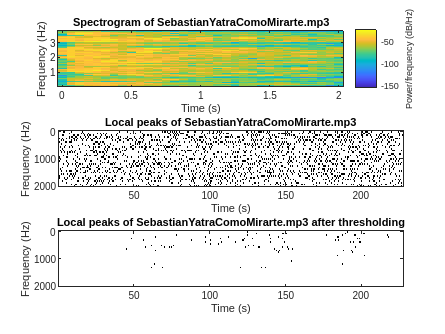

% Parameters
folder_name = '/home/laura/Desktop/univ/univ2023-1/senales/Proyecto1/parte1/Canciones'; 
fs_new = 4000;                      % New sampling rate
win_len = 64;                       % Window length in seconds
overlap_len = 32;                   % Overlap length in seconds
NFFT = 2*nextpow2(win_len*fs_new);  % Number of FFT points

% Parameters for hash table
f_tol = 4;                          % Frequency tolerance for matches (Hz)
dt_tol = 0.5;                       % Time tolerance for matches (s)
hash_table_size = 100000;           % Size of hash table

% Process all mp3 files in the folder
mp3_files = dir(fullfile(folder_name, '*.mp3'));
num_files = length(mp3_files);
num_files2 = length(mp3_files);


% Load existing song IDs and hash table
if exist('SONGID.mat', 'file') && exist('HASHTABLE.mat', 'file')
    load('SONGID.mat', 'song_ids');
    load('HASHTABLE.mat', 'hash_table');
else
    song_ids = {};                         % Create an empty cell array for song IDs
    hash_table = cell(1, hash_table_size); % Create an empty hash table
end


for i = 1:num_files

    % Check if song ID already exists in database
    [~, song_name, ~] = fileparts(mp3_files(i).name);
    if any(strcmp(song_name, song_ids))
        fprintf('Skipping %s (already in database)\n', mp3_files(i).name);
        continue;
    end

    % Read in the mp3 file
    filename = fullfile(mp3_files(i).folder, mp3_files(i).name);
    [y, fs] = audioread(filename);

    y = mean(y, 2);
    y = y - mean(y);

    % Resample to new rate
    y = resample(y, fs_new, fs);

    % Compute spectrogram
    [S, F, T] = spectrogram(y, win_len, overlap_len, 64, fs_new);
    magS = abs(S);  % Magnitude of the spectrogram 


    gs = 4;         % Distance to search in each direction

    % Find local peaks in the spectrogram
    CS1 = circshift(S, [gs 0]);
    CS2 = circshift(S, [-gs 0]);
    CS3 = circshift(S, [0 gs]);
    CS4 = circshift(S, [0 -gs]);
    P = (S > CS1) & (S > CS2) & (S > CS3) & (S > CS4);


    % Thresholding
    peaks_per_sec = 30;                       % scales the threshold
    peakMags = P.*magS;
    peaksThres = sort(peakMags(:),'descend'); % sort all peak values in order
    threshold = peaksThres(ceil(max(T)*peaks_per_sec));
    
    % Apply threshold
    if (threshold > 0)
        peaks = (peakMags >= threshold);
    end
 
    % Plot spectrogram, local peaks and thresholding
    figure;
    subplot(3,1,1)
    spectrogram(y, win_len, overlap_len, 64, fs_new);
    title(sprintf('Spectrogram of %s', mp3_files(i).name));
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');

    subplot(3,1,2)
    imagesc(T, F, P);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Local peaks of %s', mp3_files(i).name));

    subplot(3,1,3)
    imagesc(T, F, peaks);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(sprintf('Local peaks of %s after thresholding', mp3_files(i).name));

    % Set a different colormap for each subplot
    colormap(subplot(3,1,1), 'default');
    colormap(subplot(3,1,2), 1-gray);
    colormap(subplot(3,1,3), 1-gray);


    % Shows the spectrogram with blinking dots where the peaks are
    optional_plot = 0; % turn plot on or off

    if optional_plot
        % plot spectrogram
        figure;    
        [S, F, T] = spectrogram(y, win_len, overlap_len, 64, fs_new);
        spectrogram(y, win_len, overlap_len, 64, fs_new);
        title(sprintf('Spectrogram of %s with peaks', mp3_files(i).name));
        xlabel('time (s)');
        ylabel('frequency (Hz)');
    
        % plot local peaks over spectrogram
        imagesc(T, F, peaks);
        title(sprintf('Spectrogram of %s with peaks', mp3_files(i).name));
        xlabel('time (s)');
        ylabel('frequency (Hz)');
    end


    % Convert peaks to pairs
    pairs = convert_to_pairs(peaks);


    % Calculate hash for each pair
    for j = 1:size(pairs, 1)
        f1 = pairs(j, 1);
        f2 = pairs(j, 2);
        deltaT = pairs(j, 3);
        hash = simple_hash(f1, f2, deltaT, hash_table_size);
        if isempty(hash_table{hash})
            hash_table{hash} = struct('song', mp3_files(i).name, 'times', deltaT);
        else
            hash_table{hash}(end+1) = struct('song', mp3_files(i).name, 'times', deltaT);
        end
    end

end

% DATABASE

% Save song IDs and hash table to files
song_ids = {mp3_files.name};
save('SONGID.mat', 'song_ids');
save('HASHTABLE.mat', 'hash_table');